a = 1+2

a = 3

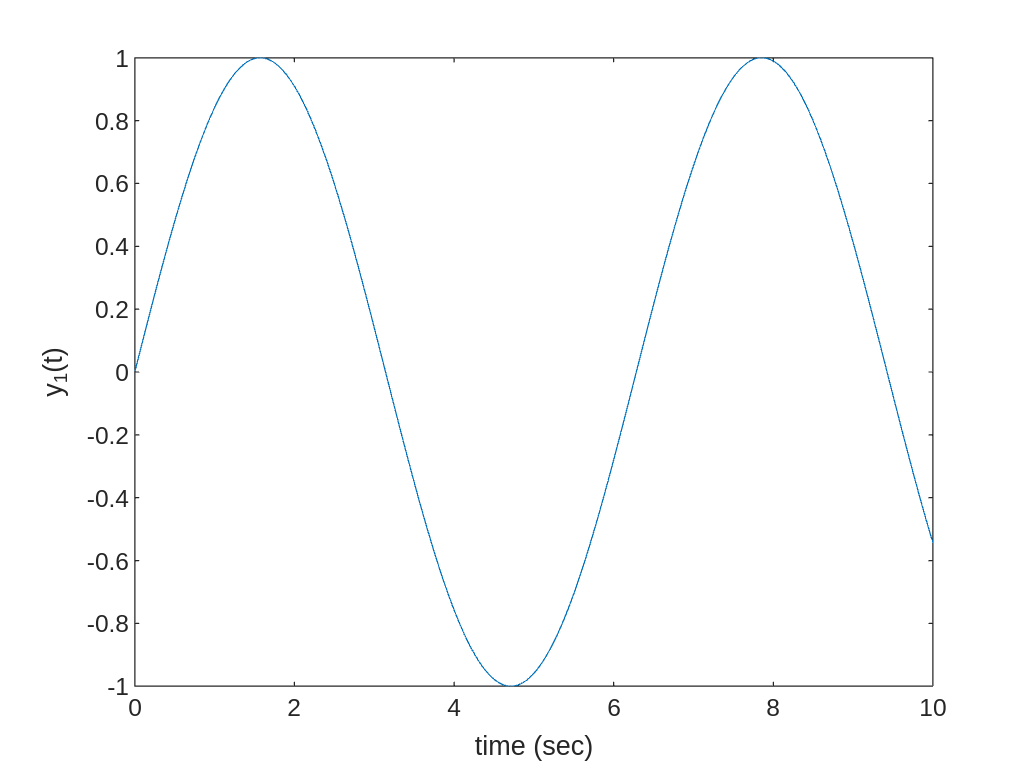

t = 0:0.01:10;
y = sin(t);
plot(t,y)
xlabel("time (sec)")
ylabel("y_1(t)")

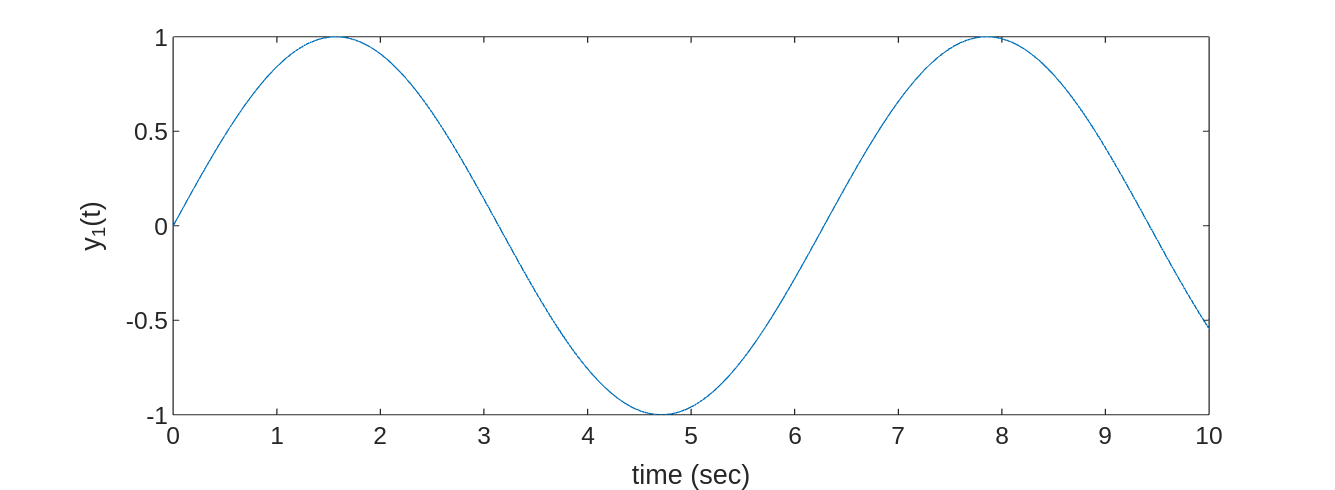

dt = 0.05;
t = 0:dt:10;
y = sin(t);
fig = figure();
fig.Position = [660 525 1182 434];
plot(t,y)
xlabel("time (sec)")
ylabel("y_1(t)")

syms t x real
y = x*sin(t)

$$y = x\,\sin\left(t\right)$$

y_dash = diff(y,t)

$$y\_dash = x\,\cos\left(t\right)$$

A = [sin(t), x*log(t);exp(x) cos(x*t)]

$$A = \left(\begin{array}{cc} \sin\left(t\right) & x\,\log\left(t\right)\\ {\mathrm{e}}^{x} & \cos\left(t\,x\right) \end{array}\right)$$

syms x_1 x_2 real
X  = [x_1; x_2]

$$X = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

f = [sin(x_1); cos(x_2)]

$$f = \left(\begin{array}{c} \sin\left(x_{1}\right)\\ \cos\left(x_{2}\right) \end{array}\right)$$

J = [diff(f(1),x_1) diff(f(1), x_2); diff(f(2),x_1), diff(f(2),x_2)]

$$J = \left(\begin{array}{cc} \cos\left(x_{1}\right) & 0\\ 0 & -\sin\left(x_{2}\right) \end{array}\right)$$

## Hi this is **a text**

J_num = double(subs(J,[x_1, x_2], [0, 0.5]))

$$J\_num = \left(\begin{array}{cc} 1 & 0\\ 0 & -\sin\left(\frac{1}{2}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{cc} 3 & 2\\ 2 & 2-\sin\left(\frac{1}{2}\right) \end{array}\right)$$

syms x1 x2 x3 x4 real
m = 1;
M = 5;
L = 2;
g = 9.8;
b = 1;
M_ = M + m*(sin(x3))^2;
f1 = x2;
f2 = m*g/M_*sin(x3)*cos(x3)-m*L/M_*sin(x3)*x4^2-b*x2/M_;
f3 = x4;
f4 = cos(x3)/L*(m*g/M_*sin(x3)*cos(x3)-m*L/M_*sin(x3)*x4^2-b*x2/M_) + g/L*sin(x3);

J = [diff(f1,x1) diff(f1,x2) diff(f1,x3) diff(f1,x4); ...
    diff(f2,x1) diff(f2,x2) diff(f2,x3) diff(f2,x4); ...
    diff(f3,x1) diff(f3,x2) diff(f3,x3) diff(f3,x4); ...
    diff(f4,x1) diff(f4,x2) diff(f4,x3) diff(f4,x4)]

$$J = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{1}{\sigma_{2}} & \sigma_{1} & -\frac{4\,x_{4}\,\sin\left(x_{3}\right)}{\sigma_{2}}\\ 0 & 0 & 0 & 1\\ 0 & -\frac{\cos\left(x_{3}\right)}{2\,\sigma_{2}} & \frac{49\,\cos\left(x_{3}\right)}{10}+\frac{\cos\left(x_{3}\right)\,\sigma_{1}}{2}+\frac{\sin\left(x_{3}\right)\,\left(\frac{x_{2}}{\sigma_{2}}+\frac{2\,{x_{4}}^{2}\,\sin\left(x_{3}\right)}{\sigma_{2}}-\frac{49\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{5\,\sigma_{2}}\right)}{2} & -\frac{2\,x_{4}\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{49\,{\cos\left(x_{3}\right)}^{2}}{5\,\sigma_{2}}-\frac{49\,{\sin\left(x_{3}\right)}^{2}}{5\,\sigma_{2}}-\frac{2\,{x_{4}}^{2}\,\cos\left(x_{3}\right)}{\sigma_{2}}-\frac{98\,{\cos\left(x_{3}\right)}^{2}\,{\sin\left(x_{3}\right)}^{2}}{5\,{\sigma_{2}}^{2}}+\frac{4\,{x_{4}}^{2}\,\cos\left(x_{3}\right)\,{\sin\left(x_{3}\right)}^{2}}{{\sigma_{2}}^{2}}+\frac{2\,x_{2}\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{{\sigma_{2}}^{2}}\\ \sigma_{2}={\sin\left(x_{3}\right)}^{2}+5 \end{array}$$

A = double(subs(J, [x1, x2, x3, x4], [4, 2, pi/2, 0.1]))

A =          0    1.0000         0         0
         0   -0.1667   -1.6333   -0.0667
         0         0         0    1.0000
         0         0    0.1683         0


eig(A)

ans =          0
   -0.1667
    0.4103
   -0.4103


clear
x = sym("x", [4,1],"real")

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4} \end{array}\right)$$